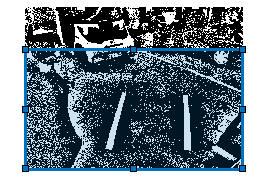

RawImg = imread("imageTest3.png");
GryImg = rgb2gray (RawImg);
bwImg = imbinarize(GryImg, 'adaptive', 'Sensitivity', 0.500000, 'ForegroundPolarity', 'bright');
imshow(bwImg)

RoadROI = drawrectangle('Position',[1 250 1275 700]);

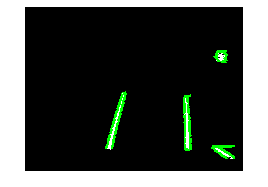

    RoiMask = uint8(RoadROI.createMask(bwImg));
    maskedImg = uint8(bwImg) .* RoiMask;

initStrel = strel('diamond',3);
erodeImg = imerode(maskedImg, initStrel);
ConnComp = bwareaopen(erodeImg , 2000);%remove components less that 1000 pixels
figure, imshow(ConnComp,[])

[L1,num1] = bwlabel(ConnComp,8);
    
    %if num1 == 0, then we should exit the function and display something like
    %no lanes in veiw
    hold on
    for k=1:1:num1
        doubt = 0;
        [c1,r1] = find(L1 == k); %Code adapted from: Digital Image Processing Using
        % Matlab - Page 362
        ymin = min(c1); %find mins and maxs of values in the component
        ymax = max(c1);
        xmin = min(r1);
        xmax = max(r1);

        xmag = xmax - xmin; %calculate the magnitude
        ymag = ymax - ymin;
        Fb = "first";


        for t=1:1:2
            if (t==2)%on our second iteration we want to graph the other side of the lane lines
                Fb = "last";
            end
      
            lastXpoint = xmax; %initate points
            lastYpoint = ymin;

            TotalEuDist = 0;
            yStep = 5;
            colour = 'g';

            for y=ymin+yStep:yStep:ymax %we want to add 5 at the start bc need to start at the second y value

                [r2] = find (c1 == y,1,Fb); %change this to last and it gets the other side
                Xpoint = r1(r2);

                %find eucledian distance with trig
                XmagPart = abs(lastXpoint - Xpoint);
                YmagPart = abs(lastYpoint - y);
                EuDist = round(sqrt(double(XmagPart.^2 + YmagPart^2)));

                TotalEuDist = TotalEuDist + EuDist;
                 
                plot([lastXpoint Xpoint],[lastYpoint y],'LineWidth',2,'Color','g')

                lastYpoint = y;
                lastXpoint = Xpoint;

            end 
         end
    end 